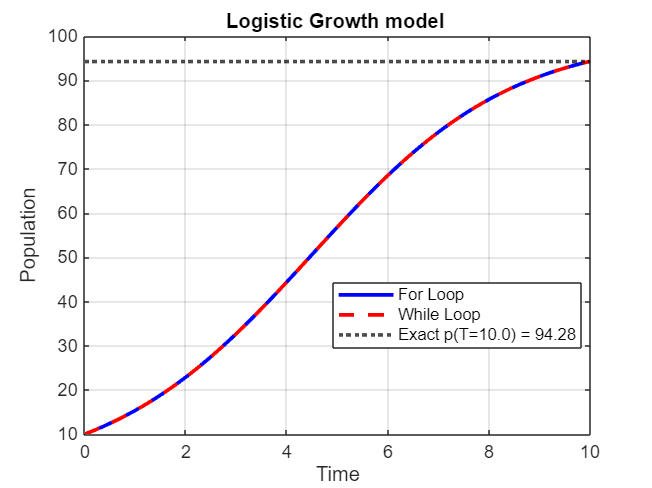

% Interactive growth simulation using the Logistic Growth model

p0 = input("Input initial population (p0): ");
r = input("Input the relative growth coefficient (r): ");
K = input("Input the carrying capacity (K): ");
maxtime = input("Input the time duration (maxtime): ");
dt = 0.1;  

t = 0:dt:maxtime;
P_for = zeros(size(t));
P_while = zeros(size(t));
P_for(1) = p0;
P_while(1) = p0;


A = (K - p0) / p0;

for i = 2:length(t)
    P_for(i) = P_for(i-1) + r * P_for(i-1) * (1 - P_for(i-1)/K) * dt;
end


j = 2;
while j <= length(t)
    P_while(j) = P_while(j-1) + r * P_while(j-1) * (1 - P_while(j-1)/K) * dt;
    j = j + 1;
end


pT_exact = K / (1 + A * exp(-r * maxtime));


figure;
plot(t, P_for, 'b-', 'LineWidth', 2); hold on;
plot(t, P_while, 'r--', 'LineWidth', 2);
yline(pT_exact, 'k:', 'LineWidth', 2);
xlabel('Time');
ylabel('Population');
title('Logistic Growth model ');
legend('For Loop', 'While Loop', sprintf('Exact p(T=%.1f) = %.2f', maxtime, pT_exact), 'Location', 'best');
grid on;